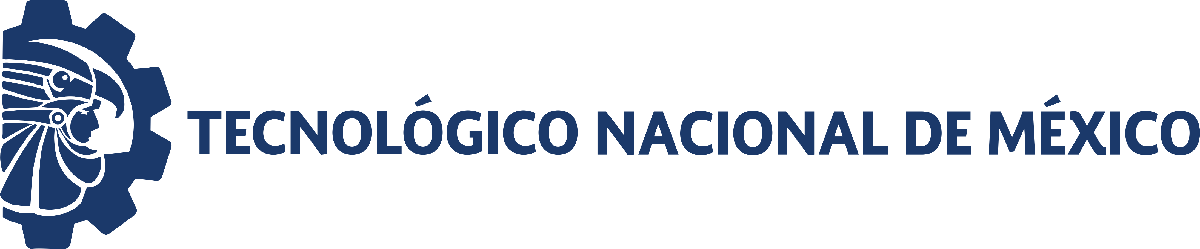                                 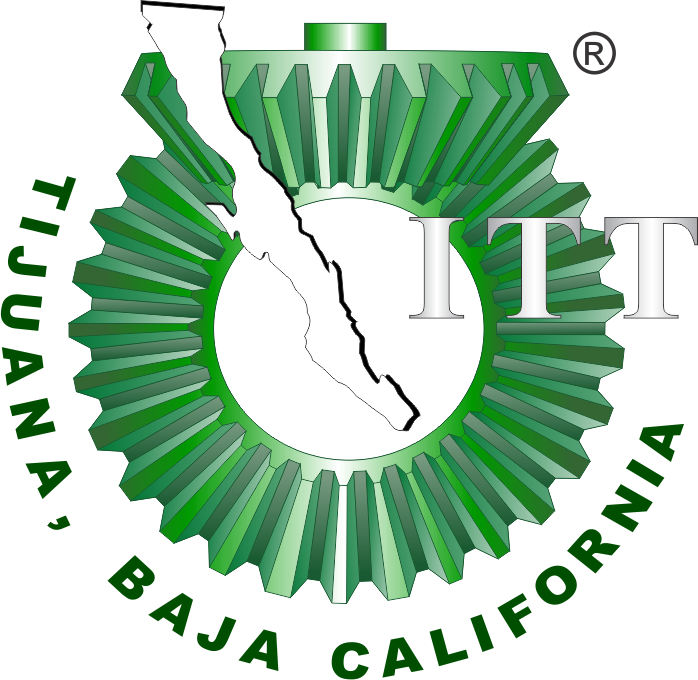

# Práctica 2: 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

Nombre del alumno: Ian Enrique Estrada Castillo

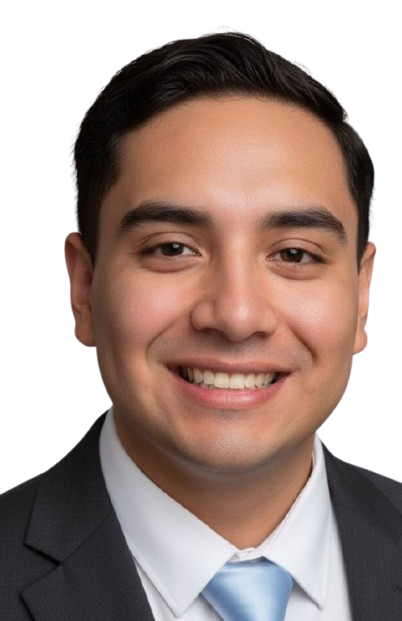

Número de control: 22211753

Correo institucional: l22211753**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

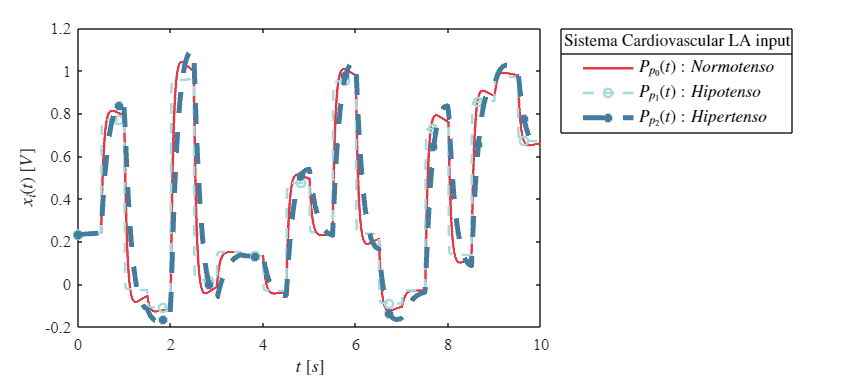

clc; clear; close all; warning('off','all')
tend = '10';
file = 'SistemaA';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
Signal='Sistema Cardiovascular LAC';
Signal2='Sistema Cardiovascular LA';
set_param('SistemaA/Ppa(t)','Minimum','-0.2');
set_param('SistemaA/Ppa(t)','Maximum','1');
set_param('SistemaA/Ppa(t)','Seed','106');
set_param('SistemaA/Ppa(t)','SampleTime','0.5');
x= sim(file,parameters);
writematrix(x.Ppa,'Signal.xlsx')
plotsignals2(x.t, x.Pp0, x.Pp1, x.Pp2, Signal2);

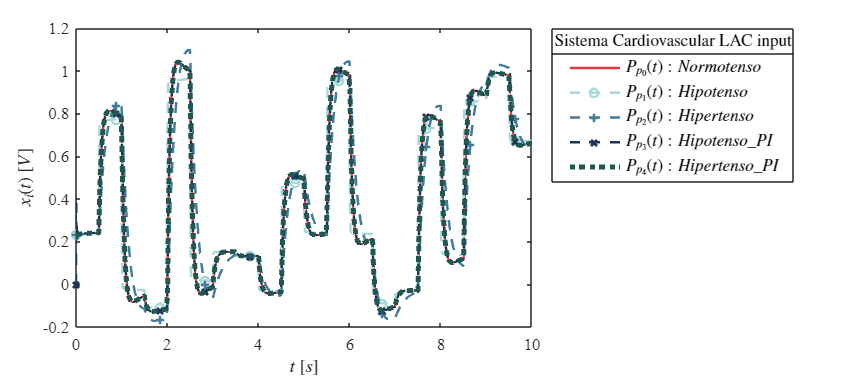

plotsignals(x.t,x.Pp0,x.Pp1,x.Pp2,x.Pp3,x.Pp4,Signal);

## Función: Respuesta a las señáles

function plotsignals(t,Pp0,Pp1,Pp2,Pp3,Pp4,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'Fontname','Times New Roman','FontSize',10)
    hold on;grid off;box on;
    mycolor = [0.902,0.224,0.274;
               0.659,0.855,0.863
               0.271,0.482,0.616
               0.114,0.208,0.341
               0.133,0.341,0.310
               0.569,0.392,0.235];
    colororder(mycolor)
    p = plot(t,Pp0,'-',t,Pp1,'--o',t,Pp2,'--+',t,Pp3,'--x',t,Pp4,':',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(5), 'LineWidth',3); 
    L = legend('$P_{p_0}(t):Normotenso$','$P_{p_1}(t):Hipotenso$','$P_{p_2}(t):Hipertenso$','$P_{p_3}(t):Hipotenso\_PI$','$P_{p_4}(t):Hipertenso\_PI$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[Signal,' input'],"FontSize",10);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','vector')

end

function plotsignals2(t,Pp0,Pp1,Pp2,Signal2)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'Fontname','Times New Roman','FontSize',10)
    hold on;grid off;box on;
    mycolor = [0.902,0.224,0.274;
               0.659,0.855,0.863
               0.271,0.482,0.616];
    colororder(mycolor)
    p = plot(t,Pp0,'-',t,Pp1,'--o',t,Pp2,'--+',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3), 'LineWidth',3); 
    L = legend('$P_{p_0}(t):Normotenso$','$P_{p_1}(t):Hipotenso$','$P_{p_2}(t):Hipertenso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[Signal2,' input'],"FontSize",10);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    exportgraphics(gcf,[Signal2,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal2,'.png'],'ContentType','vector')

end